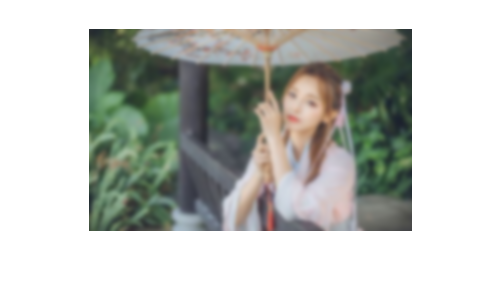

clc;clear all;close all;
im=double(imread('Image1.jpg'));
get=inputdlg(["What's the radius?","What's the variance?"],'Input');%input
r=str2double(get{1}); % get user input:radius
o=str2double(get{2}); % get user input:variance
% generate convolution kernel using normal distribution
nm=zeros(2*r+1,2*r+1);
for i=-r:r
    for j=-r:r
        nm(i+r+1,j+r+1)=exp(-(i*i+j*j)/(2*o*o))/(2*pi*o*o);
    end
end
nm=nm./sum(nm,'all');% remain the same brightness,let the sum of kernel be 1
res=imfilter(im,nm,'replicate');
figure,imshow(uint8(res));